# Solutions to Coding Problems

## Exercise 3

### Part 1

% We chose boat 2, which has a width of deck width of 1m, a deck height of
% 0.5m, a length of 0.6m, and a bottom hull shape of D(2x/W)^2 and a
% density (rho) of 250 kg/m^3
W = 1; % m
D = 0.5; % m
L = 0.6;  % m
h = 0.2; % m
d = 0.2; % m
theta = 90;
R = [cosd(theta) -sind(theta); sind(theta) cosd(theta)];
rho100 = 1250; % kg/m^3
rho50 = 0.50 * rho100; % kg/m^3
rho_water = 1000; % kg/m^3

fun_rho = @(y) rho100 * 0.2; % rho100 * (y < h) + rho50 * (y >= h);

% we define xPoints and zPoints to be a linear space over the appropriate
% range.  While we could avoid defining these intermediate variables (and just
% put the linspace into the call to meshgrid), we will need them in part 2.
% The call to meshgrid defines matrices X and Z, and we gather those into a
% variable called P (for points). Notice that P has 2 rows (x and z) and 10000
% columns (100x100 points)
xPoints = linspace(-1.5, 1.5, 250);
zPoints = linspace(-1.5, 1.5, 250);
[X, Z] = meshgrid(xPoints, zPoints);
P = [X(:)'; Z(:)'];

### Part 2

P_rot = R * P;
% We find all of points that are inside the boat using some logic - the z
% coordinate has to be above the hull but below the deck. The variable
% "insideboat" will be 1 if true and 0 if false. We transpose the result to
% create a column vector
insideBoat = transpose(P_rot(2,:) >= D*(2*P_rot(1,:)/W).^2 & P_rot(2,:) <= D);
underWaterAndInsideBoat = (P(2, :) <= d)' & insideBoat;
% the area of each little cell
deltaA = (xPoints(2)-xPoints(1))*(zPoints(2)-zPoints(1));
% insideBoat will zero out any mass outside of the boat, rho is the density,
% so we multiply by the volume, which is deltaA times the length.
masses = (insideBoat*deltaA*L).*fun_rho(P(2, :)');
mass_boat = sum(masses)

mass_boat = 50.9943

masses_water = (underWaterAndInsideBoat*deltaA*L).*rho_water;
mass_water = sum(masses_water)

mass_water = 160.7781

mass_diff = mass_boat - mass_water

mass_diff = -109.7837

displacement_ratio = mass_boat / mass_water % If this is less than 1, the boat floats!

displacement_ratio = 0.3172

if (displacement_ratio < 1)
    disp("The boat floats!")
elseif (displacement_ratio == 1)
    disp("The boat is neutrally bouyant!")
else
    disp("The boat sinks!")
end

The boat floats!


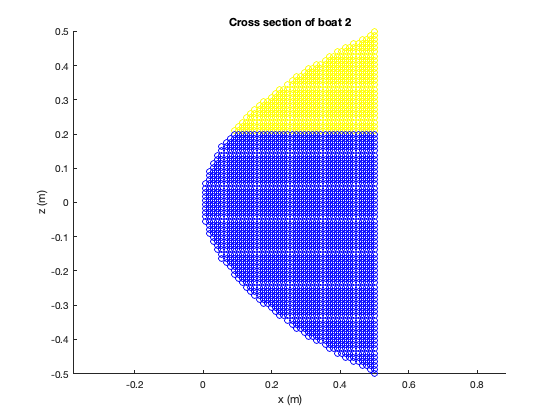


% plot only the points that are in the boat
clf
hold on;
scatter(P(1,insideBoat),P(2,insideBoat),'y');
scatter(P(1,underWaterAndInsideBoat),P(2,underWaterAndInsideBoat),'b');
xlabel('x (m)');
ylabel('z (m)');
title('Cross section of boat 2');
axis equal;
hold off;

### Part 3

% The numerator gives us the mass-weighted sum of the 2d position vectors
% and the denominator gives us the total mass (we could also use
% sum(masses), but this keeps the connection to matrix multiplication
% clearer
CoM = (P*masses)/(dot(ones(size(masses)), masses))

CoM =     0.3031
    0.0000


## Exercise 4

% the water would be at 0.2m
d = 0.2;    % m
underWater = (P(2,:) <= d)';  % test if each part of the meshgrid is under the water
underWaterAndInsideBoat = insideBoat & underWater;  % the & returns 1 if both conditions are true
areas = underWaterAndInsideBoat*deltaA;
volumes = underWaterAndInsideBoat*L;
mass_underwater = sum(volumes .* rho_water)

mass_underwater = 1107600

% the center of buoyancy is given by the exact same calculation except we
% use areas instead of masses
CoB = (P*areas)/(dot(ones(size(areas)), areas))

CoB =     0.2896
   -0.0833


## Exercise 5

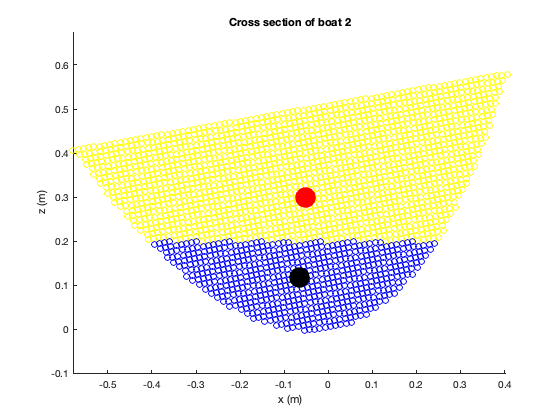

% let's rotate the boat by 100 degrees
theta = 100;
% We meet again old friend (our 2d rotation matrix)
R = [cosd(theta) -sind(theta); sind(theta) cosd(theta)];
% We can rotate all of the points in one fell swoop using matrix multiplication
Protated = R*P;

% see above for motivation behind this formula (make sure to operate on
% your rotated points)
CoM = (Protated*masses)/(dot(ones(size(masses)), masses));

underWater = (Protated(2,:) <= d)';
underWaterAndInsideBoat = insideBoat & underWater;
areas = underWaterAndInsideBoat*deltaA*L;

% again, see above for motivation
CoB = (Protated*areas)/(dot(ones(size(areas)), areas));

% now plot the rotated boat
clf
scatter(Protated(1,insideBoat), Protated(2,insideBoat),'y');
xlabel('x (m)');
ylabel('z (m)');
title('Cross section of boat 2');
hold on;
% identify the part of the boat that is underwater
scatter(Protated(1,underWaterAndInsideBoat), Protated(2,underWaterAndInsideBoat),'b');
% finally we identify the CoM and CoB and see if they make sense. The 5000 controls 
% the size of the point.  Using 'r.' for instance, gives
% us a filled in point that is red
scatter(CoM(1), CoM(2), 5000, 'r.');
scatter(CoB(1), CoB(2), 5000, 'k.');
axis equal;